ur5 = loadrobot("universalUR5");
q = homeConfiguration(ur5);

control_points = [
    tform2trvec(getTransform(ur5, q, 'tool0')); % ตำแหน่งปัจจุบัน
    0.0, 0.2, 0.0;
    0.4, 0.3, 0.3;
    0.5, 0.2, 0.5;
    0.2, 0.4, 0.3;
    0.1, 0.8, 0.2;
];
[trajectory,velocity] = TrajectoryGenerator(control_points,5,5);

All Trajectory Success


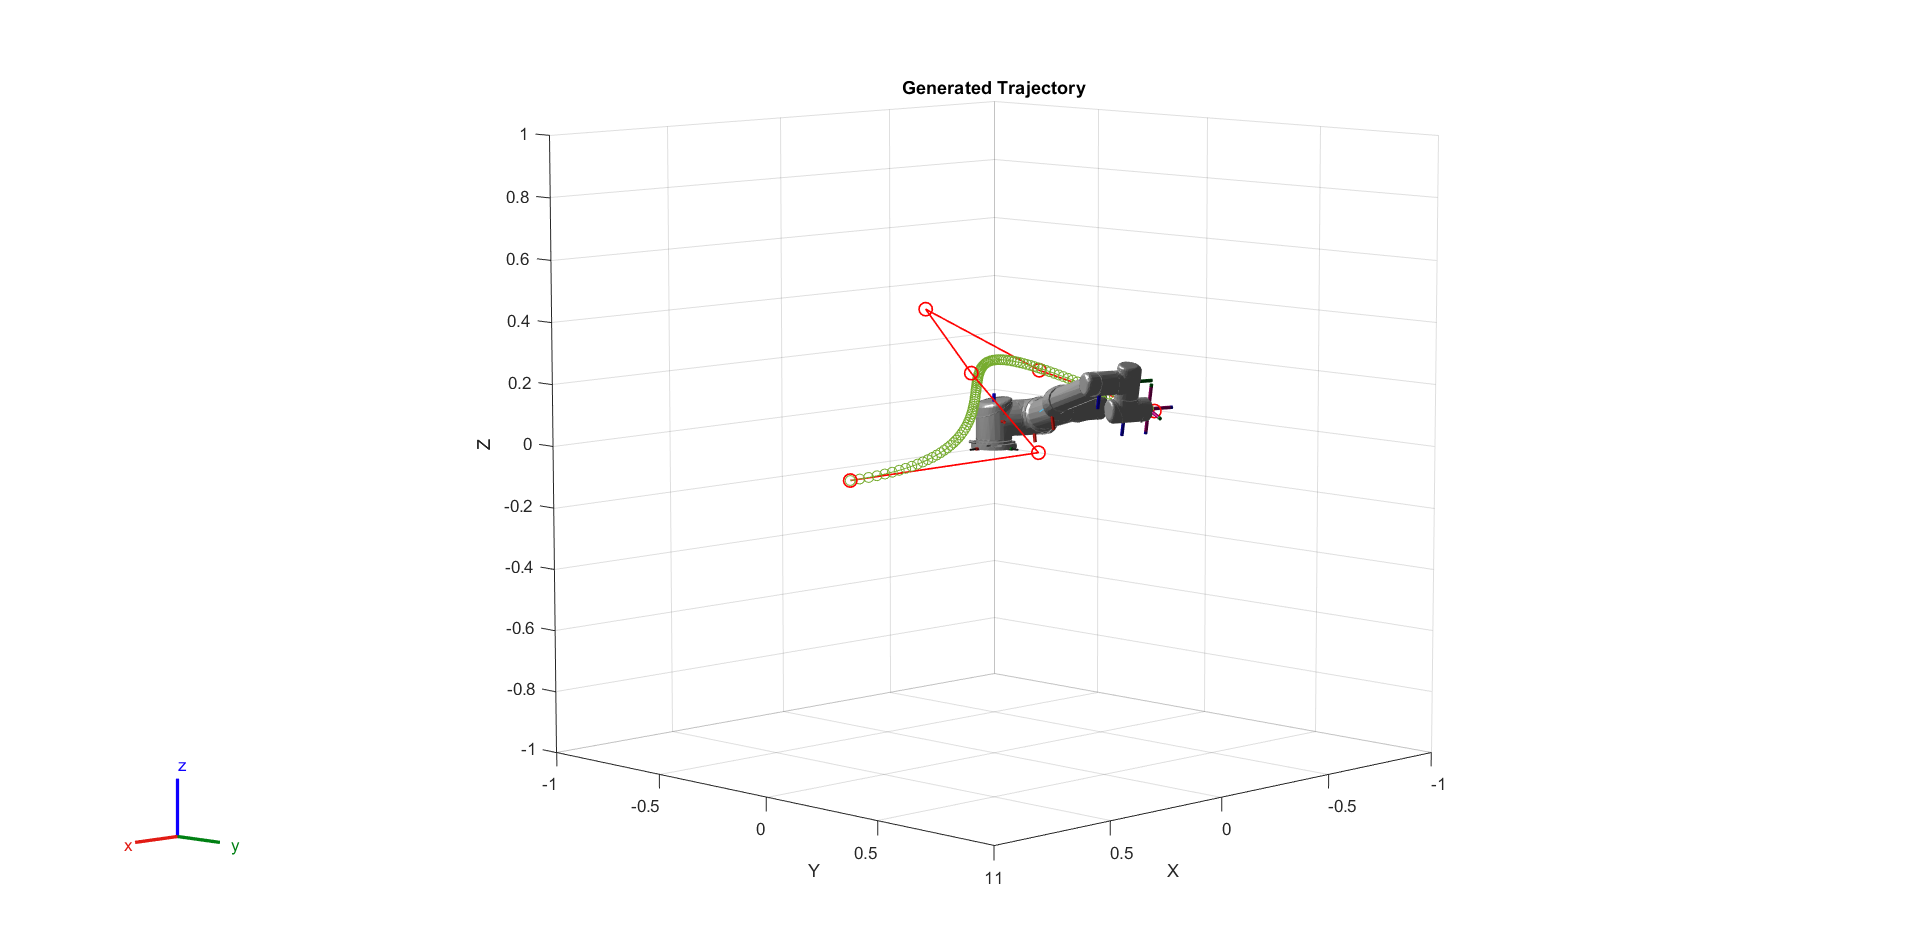

if checkIKForTrajectory(ur5, trajectory, q)
    disp("All Trajectory Success");

    % แปลง Task Trajectory เป็น Joint Trajectory
    joint_traj = Task2JointTrajectoryMapper(ur5, trajectory, q);

    % เคลื่อนที่ตาม Trajectory
    figure;
    show(ur5, q, 'Frames', 'on', 'PreservePlot', false, 'Collisions', 'off', 'Visuals', 'on');
    hold on;
    plot3(control_points(:,1), control_points(:,2), control_points(:,3), 'ro-', 'LineWidth', 1, 'MarkerSize', 8);
    plot3(trajectory(:,1), trajectory(:,2), trajectory(:,3), '-o');
    xlabel('X'); ylabel('Y'); zlabel('Z');
    title('Generated Trajectory');
    grid on;

    % Loop เคลื่อนที่ตาม Joint Trajectory
    for i = 1:size(joint_traj, 1)
        % อัปเดตค่ามุมข้อต่อ
        for j = 1:numel(q)
            q(j).JointPosition = joint_traj(i, j);
        end

        % แสดงตำแหน่งหุ่นยนต์
        show(ur5, q, 'Frames', 'on', 'PreservePlot', false);
        pause(0.05); % หน่วงเวลาเพื่อให้เคลื่อนไหวสมจริง
    end
else
    disp("Some points in Trajectory failed IK.");
end